# Simulating the 5G NR PDSCH over a Fading Channel 

In thisl lab, we will build a simple transmitter and receiver for the 5G NR downlink data channel, called the Physical Downlink Shared Channel or PDSCH.  We will perform the downlink simuation over a fading channel.  Writing this simulation from scratch would be months of work given all the complexity of the NR standard.  However, in this lab, we will be able to use [MATLAB's 5G Toolbox](https://www.mathworks.com/help/5g/index.htm) which has incredible functions to perform all the basic operations.  

In going through the lab, you will learn to:

- Describe and visualize the OFDM frame structure of the NR standard including slots, subframes, and frames in time and sub-carriers and resource blocks in frequency.

- Configure an OFDM channel with the 5G Toolbox.

- Create a mutli-path channel in frequency domain for the OFDM link.

- Measure the variation in SNR over one slot and over multiple slots to determine the effects of fast and slow fading.

- Configure a PDSCH transmission including its resource block allocation and MCS.

- Use 5G Toolbox commands to compute the transport block size, and perform the transmit steps including scrambling, LDPC encoding, symbol mapping and resource mapping to the OFDM grid.

- Use 5G Toolbox commands to perform the RX steps including resource extraction, MMSE equalization, LDPC decoding, and 

Some of the code in this lab is based on  [MATLAB's PDSCH throuhput demo](https://www.mathworks.com/help/5g/ug/nr-pdsch-throughput.html).  You will need to get the R2020B version of MATLAB's 5G Toolbox for the demo.  The Toolbox is rapidly evolving, and I have used some functions that are not available in R2020A.  Also, along with this file, you will see three other files:

- `FDChan.m`:  A class for frequency-domain channel simulation

- `NRgNBTxFD.m`:  A class for NR gNB TX frequency-domain simulation

- `NRUERxFD.m`:  A class for NR UE RX frequency-domain simulation

These files have some TODO sections to be completed.

**Submission**:  Complete this MATLAB live file and the other files.  Run the code.  Print all the files to PDF.  Merge to a single PDF and submit the PDF for grading.

## 5G NR OFDM Channel Background

One of the main goals of the 5G NR standard was to build a highly configurable channel structure that can operate in a range of frequencies and band allocations.  The figure below are taken from this excellent website: [https://www.rfwireless-world.com/5G/5G-NR-Numerology-or-Terminology.html](https://www.rfwireless-world.com/5G/5G-NR-Numerology-or-Terminology.html) 

To enable configuration, the 5G NR standard uses OFDM with a configurable time and frequency structure.  For the time structure, time is divided into** radio frames** of 10 ms, which are then divided into 10 **sub-frames** of 1ms each.  The subframes are then divided into **slots** where the number of slots per subframe are configurable.  Specifically, the NR channel has a basic **configuration parameter** `mu=0,1,...,4, `and the number of slots per subframe is `2^mu.  `

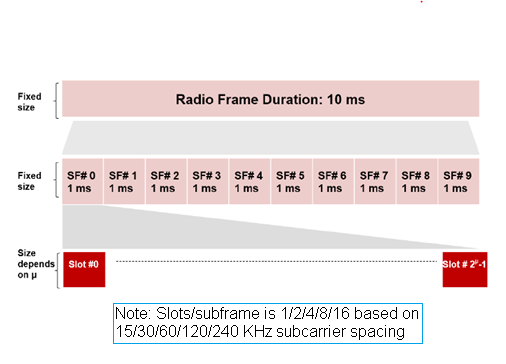

In frequency, the channel uses OFDM with a sub-carrier spacing `Delta f,` that is tied to the configuration `mu.  `In each slot, the bandwidth is then divided into what are called **resource blocks** **(RBs) **which are 12 subcarriers for one slot.  The total bandwidth is then controlled by configuring the total number of resource blocks.  The sub-carrier spacing and the minimum and maximum number of RBs for each configuration `mu` is shown below.

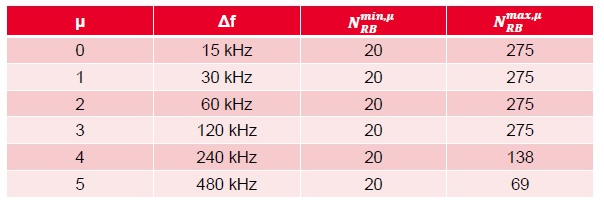

Finally, each slot is divided into OFDM symbols.  The number of symbols per slot is 14 for what is called the normal cyclic prefix and 12 for extended cyclic prefix.  Most systems use normal CP.  The extended CP is used for environments with very large delay spreads.

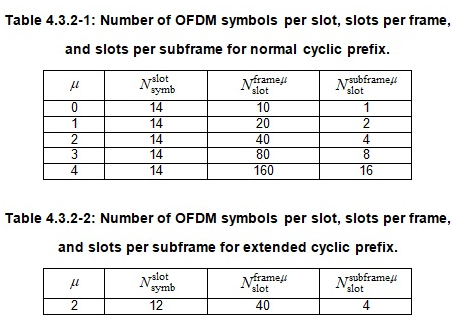

## Configuring the OFDM Channel

In this lab, we will configure the parameters for an OFDM channel at a carrier frequency of 28 GHz.  We will use the following parameters, which are widely-used in these frequencies.

fc = 28e9;                % Carrier frequency
SubcarrierSpacing = 120;  % SCS in kHZ
NRB = 66;  % number of resource blocks

Using the SCS and number of resource blocks, compute and print the bandwidth occupied by this waveform.

nscPerRB = 12;  % number of sub-carriers per RB

% TODO:
%  bwMHz = ...


In the 5G Toolbox, you can configure the channel with the `nrCarrierConfig` command which creates an object with all the relevant parameters.  Use the `nrCarrierConfig` command to create a `carrierConfig` structure with the `SubcarrierSpacing` from above and the property NSizeGrid set to `NRB`.

% TODO
%   carrierConfig = nrCarrierConfig(...)

Given the `carrierConfig` we can the configuration of the waveform with following command:

waveformConfig = nrOFDMInfo(carrierConfig);

Use the `waveformConfig` structure to print:

- The sample rate in MHz

- Number of OFDM symbols per subframe

% TODO

## Configuring a Frequency-Domain OFDM Channel

In this lab, we will simulate the channel in frequency domain.  For OFDM systems, frequency-domain simulation enables us to avoids the need to simulate the TX and RX filtering, synchronization and channel estimation.  We can add these components of the simulation later.  We will use the following simple channel with two paths.

% Parmaeters for each path
gain = [0,-3]';      % path gain in dB
dly = [0, 200e-9]';  % path delays in seconds
aoaAz = [0, 180]';  % angles of arrival
aoaEl = [0, 20]';

% Mobile velocity vector in m/s
rxVel = [30,0,0]';

% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
EsN0Avg = 20;   % Average SNR

The lab material contains a file, `FDChan.m` which has a skeleton for modeling channels in frequency domain.   You can create this channel object using this file with the following command:

fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
    'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', fc);

The file `FDChan.m` has various sections labeled `TODO` that should be completed.  First, complete the section in the constructor that sets complex gains for each path

The vector `gainComplex` should have one complex value for each path, with the gain set by gaindB and a random complex phase from `[0,2*pi]` .

Next, set the Doppler for each path based on the mobile velocity and angles of the path. by completing the following part:

Edit the code, recreate the `fdchan` object and print the Doppler shifts:

% TODO:  Print fdchan.fd


For the fd simulator, we will also need to compute the time of the OFDM symbols relative to the beginning of the sub-frame.  Complete the following section in the `FDChan` class to create a vector obj.symStart where `obj.symStart(i) is the time, in seconds, of the start of the `i`-th OFDM symbol relative to the beginning of the subframe.  You can use the waveformConfig.SymbolLengths and waveformConfig.SampleRate.  

 Plot `fdchan.symStart.  `If you did this correctly, the values should go from 0 to 1ms.

% TODO

## Simulating the Frequency-Domain Channel

The method, `FDChan.stepImpl()` takes as an input an array, `txGrid(n,j),` representing the TX OFDM data on sub-carriers `n` and OFDM symbol numbers j.  The output grid is given by,

where the channel is:

and `time(j)` is the start time of the `j-`th symbol and `scs` is the sub-carrier spacing.  The noise variance is set to obtain a cerain average SNR  given by,

The average channel gain is 

Use these formulae to complete the method `stepImpl`.

% TODO:  Complete complete the method FDChan.stepImpl()

To test the channel, we will create a TX grid corresponding to one slot.  You can do this with the following command.

NumLayers = 1;
txGrid = nrResourceGrid(carrierConfig, NumLayers);
txGrid(:) = 1;


Use the `fdchan.step()` method to find the channel and noise variance on this grid at subframe number, `sfNum=0` and slot number, `slotNum=0`.  Compute the SNR in dB over the grid and plot the SNR using the `imagesc` command.  You should see there is a high level of variation of the SNR across the slot indicating significant **fast fading**.

% TODO

We will now look at the average SNR over different slots.   Suppose we transmit on `slotNum=0` for `sfNum=i` for `i=0,...,ntx` for `ntx=100. ` Hence, we are transmitting once per subframe.  For each transmission, compute the channel and the average SNR.  Plot the average SNR as a function of the transmission number.  You should see that it is very constant.  Thus, although individual resource elements are fading, the average SNR experienced over different blocks indicating that there is **neglible** **slow fading**.  

% TODO


## Creating a Simple NR PDSCH Transmitter

Downlink data (the link from the base station to the UE) in the NR system is transmitted on what is called the PDSCH channel or Physical Downlink Shared Channel.  It is called *shared* since multiple UEs share the channel.  Each transmissions is called a transport block.  The transport block occupies one slot with a variable number of resource blocks.  Multiple UEs can be scheduled in the slot on different resource blocks.  When we discuss MIMO technologies, users will also be able to be transmitted on different *streams* or layers, but for now we will just use a single antenna system with one layer.

Each transport block has one of 28 **modulation and coding scheme (MCS) **given by this table.

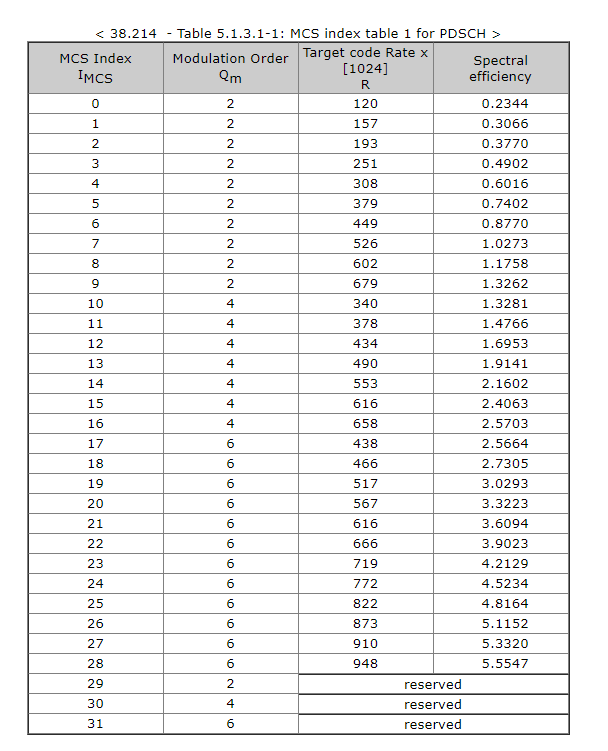

For this simulation we will use MCS=13.  

mcsInd = 13;

% TODO
%    Modulation = 'QPSK', '16QAM' or '64QAM'
%    targetCodeRate = ...

Once you have selected these parameters, we can confgure the PDSCH transmission with the following command.  In this case, I have configured the PDSCH to use all the RBs and all but the first OFDM symbol in a slot.  I have also added what is called the phase tracking reference signal (PTRS) for mitigating phase noise.  We will discuss this channel more later when we disucss equalaization.

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'EnablePTRS', 1,...
    'PTRS', nrPDSCHPTRSConfig());

The NR has an extremely complex way of transmitting data involving LDPC encoding, scrambling, mapping to QAM symbols and then placing the symbols on the RX grid.  These would takes months of time to write from scratch.  The 5G toolbox has amazing functions to do all of this for you.  

I have created a simple TX class using these functions.  You will not need to modify it.  But, we will just look at the outputs.  You can create an instance of this class as follows.

tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

You can then call the `step` method to generate random bits for one slot of data based on the PDSCH configuration.  If you look at the code in the step implementation you can see the MATLAB 5G Toolbox commands to encode and modulate the data.

txGrid = tx.step();

Use the `imagesc` command to plot the set of resource elements in the grid where `txGrid` is non-zero.  These are the resource elements (REs) where the PDSCH channel is allocated.  You should see that the PDSCH is allocated except at the following locations:

- The first OFDM symbol.  This is where the assignment channel, called the PDCCH, will go.  Basically this communicates to the UEs the resource allocation, UE identity in that slot.  We will discuss

- The third OFDM symbol. which is used as demodulation reference signal (DM-RS) used in channel estimation.  We will discuss this when we discuss equalization

- The horizontal strips.  These are PT-RS for phase noise mitigation that we will also discuss later.

% TODO

Next, compute and print:

- The number of REs allocated to the PDSCH in the slot

- The fraction of PDSCH REs to the total number of REs.

% TODO
%   nREPdsch = ...
%   bwFrac = ...



Next, let's look at the transmitted QAM symbols.  The NR standard has a complex mapping of the PDSCH to the REs..  We can use the following command to get the indices, `pdschInd`,  of the PDSCH locations for a given configuraiton.  It also returns a structure, `pdschInfo` with other modualtion data.

% Get indices on where the PDSCH is allocated
[pdschInd,pdschInfo] = nrPDSCHIndices(carrierConfig, pdschConfig);


Use the PDSCH symbols from `txGrid` from the `pdschInd` and plot the resulting constellation diagram.  You should see a 16-QAM constellation with unit average power.

% TODO
%  pdschSym = ...

Finally, let's compute the spectral efficiency.  In NR, the transmitted information bits for a transport block can be stored in either one or two codewords.  For this configuration, there will only be one codeword (two codewords are used when there are more than four spatial streams).  The randomly generated information bits in the transmission are stored in a field, `tx.txBits{1}.  `Compute and print:

- The number of information bits that were transmitted in this transport block.

- The spectral efficiency, meaning the number of information bits per PDSCH RE.

The spectral efficiency should be close to the target spectral efficiency in the MCS table.

% TODO


## Building an NR Receiver

We will next build a simple NR receiver at the UE.  I have written most of the code containe in a class `NRUERxFD`.    However, there are a few sections labeled `TODO` in the `stepImpl` method.  These just call built-in functions from the 5G Toolbox for equalization, LLR computation and decoding.  You just need to supply each function with the correct inputs.   

Once you have completed the `TODO` parts, an RX object can be created as follows.

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

Now test the receiver:

- Create a `NRgNBTxFD` transitter object, `tx` as above.  

- Run the TX to create one slot of symbols.

- Create an `FDChan` object as above with the two paths and an average SNR of 20 dB.

- Run the `txGrid` through the chanel at slot = 0 and subframe = 0

- Create a RX object, `rx` of type `NRUERxFD.`

- Run the RX grid, channel grid and noise variance into the RX

- Make sure that `rx.rxBits == tx.txBits{1}`.  

% TODO:  Create the TX
%   tx = NRgNBTxFD(...)
%   txGrid = ...
%   fdchan = FDChan(...);
%   [...] = fdchan.step(...);
%   rx.step(...);


Also, plot the equalization constelllation stored in the RX.

% TODO



## Testing the Receiver Performance

The above validated the performance of the RX at high SNR.  Now vary the SNR, `EsN0Avg` from 5 to 10 dB in 1 dB steps.  In each SNR, simulate the link above with repeated transmissions one subframe apart.  At each SNR, repeat until either:

- You get 50 block errors, or

- You have tested at least 500 TX

Once you have a SNR with zero block errors, you can stop and not continue to the higher SNRs.  Measure the block error rate at each SNR.  This may take a few minutes.

Plot the BLER vs. SNR.  If you do everything correctly, you should get that the BLER goes to zero Es/N0=8 dB.

% TODO:  Compute BLER vs. EsN0Avg



% TODO:  Plot BLER vs EsN0Avg


## Estimating the Shannon Ergodic Capacity

We conclude by estimating the theoretical Shannon capacity over a typical slot.  The Shannon ergodic spectral efficiency is:

where `chanGrid` are the complex channel gains on the OFDM grid and gamma is the average Es/N0.

Compute this Shannon spectral efficiency vs. EsN0 for 0 to 10 dB.  You should see that theoretically, you can achieve the spectral efficiency in the MCS of 1.9 bps/Hz at about Es/N0 = 5.3 dB.  So, the NR code only runs about 2 to 2.5 dB below Shannon capacity.

% TODO


